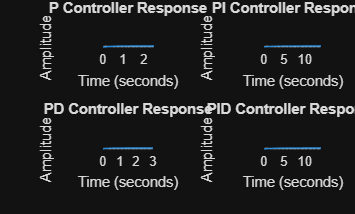

clc;
clear;
close all;

% Define Laplace variable
s = tf('s');

% Plant (Example Second Order System)
G = 1/(s^2 + 10*s + 20);

% Controller gains
Kp = 5;
Ki = 10;
Kd = 1;

% Controllers
P_controller  = Kp;
PI_controller = Kp + Ki/s;
PD_controller = Kp + Kd*s;
PID_controller = Kp + Ki/s + Kd*s;

% Closed loop systems
sys_P   = feedback(P_controller*G,1);
sys_PI  = feedback(PI_controller*G,1);
sys_PD  = feedback(PD_controller*G,1);
sys_PID = feedback(PID_controller*G,1);

% Step responses
figure;

subplot(2,2,1)
step(sys_P)
title('P Controller Response')
grid on

subplot(2,2,2)
step(sys_PI)
title('PI Controller Response')
grid on

subplot(2,2,3)
step(sys_PD)
title('PD Controller Response')
grid on

subplot(2,2,4)
step(sys_PID)
title('PID Controller Response')
grid on


% Performance comparison
disp('Step Response Characteristics')

Step Response Characteristics



info_P = stepinfo(sys_P)

info_P = struct with fields:
         RiseTime: 0.6717
    TransientTime: 1.1668
     SettlingTime: 1.1668
      SettlingMin: 0.1804
      SettlingMax: 0.2000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2000
         PeakTime: 2.3855


info_PI = stepinfo(sys_PI)

info_PI = struct with fields:
         RiseTime: 4.3265
    TransientTime: 7.8763
     SettlingTime: 7.8763
      SettlingMin: 0.9006
      SettlingMax: 0.9997
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9997
         PeakTime: 16.1604


info_PD = stepinfo(sys_PD)

info_PD = struct with fields:
         RiseTime: 0.5557
    TransientTime: 1.0662
     SettlingTime: 1.0662
      SettlingMin: 0.1802
      SettlingMax: 0.2000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.2000
         PeakTime: 3.1799


info_PID = stepinfo(sys_PID)

info_PID = struct with fields:
         RiseTime: 4.4631
    TransientTime: 7.7703
     SettlingTime: 7.7703
      SettlingMin: 0.9016
      SettlingMax: 0.9997
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9997
         PeakTime: 15.7939
